# Sign Perturbed sums

#### Data generator

clear all;
% Define ARX model parameters
% y(t) - 0.33 y(t-1) = 0.22u(t-1) + 0.15e(t-1) + e(t) 
% u(t) = 0.31 y(t) + 0.23 y(t-1) controller
theta_real = [0.44, 0.33, 0]

theta_real =     0.4400    0.3300         0


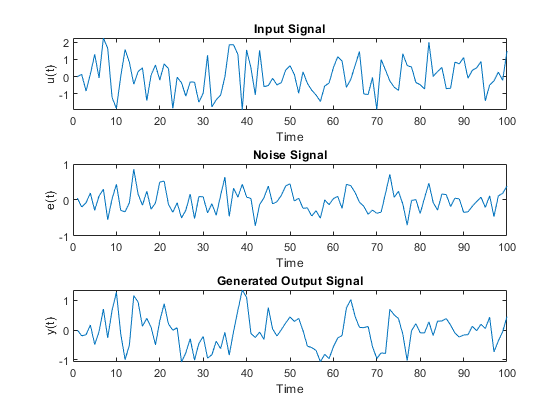

A = [1, -theta_real(1)];   % AR coefficients
B = [0, theta_real(2)];       % MA coefficients
C = [1, theta_real(3)];       % input coefficients
D = 0;           % Constant term
noiseVar = 0.1;  % Variance of the noise
seed = 100; % You can choose any integer value
rng(seed);

% Create an instance of ARMAXGenerator
armaxGen = ARMAXGenerator(A, B, C, D, @custom_past_y);



% Generate data
n = 100; % Number of data points
%e = generateLaplaceRV(n, 0, noiseVar);
e = randn(n, 1)*sqrt(noiseVar); % Noise sequence
[y, u, e] = armaxGen.generateData(n,e);
% Plot the generated data
armaxGen.plotData(y, u, e);


%%%%% PEM estimate
% Define the model orders
na = 1; % Order of A(z^-1)
nb = 1; % Order of B(z^-1)
nc = 0; % Order of C(z^-1)
nk = 1; % Input delay

% Package data into iddata object
data = iddata(y, u, 1);

% Create the ARMAX model structure
model_init = armax(data, [na nb nc nk]);

% Estimate the model parameters using PEM
pem_model = pem(data, model_init)

pem_model =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.4869 z^-1                           
                                                   
  B(z) = 0.04796 z^-1                              
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=1
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using PEM on time domain data "data".  
Fit to estimation data: 12.56% (prediction focus)
FPE: 0.2424, MSE: 0.2328                         


pem_theta = [-pem_model.A(2), pem_model.B(2)]

pem_theta =     0.4869    0.0480


%pem_theta = [-pem_model.A(2), pem_model.B(2), pem_model.C(2)]

SPS

% Define confidence probability and number of random signs
% Define SPS parameters
m = 40;   % Integer m
q = 5;    % Integer q 
p = 1-q/m %Confidence probability p = 1 − q/m

p = 0.8750

T = 1;
% Create an instance of SPS
sps = SPS(p, m, q, n, T);
% Generate random signs and permutation
conf_region = [];  % Initialize an empty array to store the confidence region points
sps = sps.generateRandomSignsAndPermutation();
% 
% for a = 0:0.005:0.85
%     for b = 0:0.005:0.51
%         %c = pem_theta(3);
%         c=0;
%         %for c = 0:0.1:1
%             A_hat = [1, -a];       % AR coefficients
%             B_hat = [0, b];       % MA coefficients
%             C_hat = [1, c];       % input coefficients
%             D_hat = 0;            % Constant term
%             % Check the condition using the sps_indicator function
%             if sps.sps_indicator(y, u, A_hat, B_hat, C_hat, D_hat, @custom_past_y, @createFeatureMatrix) == 1
%                 % Add the pair [a, b] to conf_region
%                 conf_region = [conf_region; a, b, c];
%             end   
%         %end
%     end
% end

% multithreading version
% Initialize the parallel pool (optional)
if isempty(gcp('nocreate'))
    parpool;
end

Starting parallel pool (parpool) using the 'local' profile ...




% Define the range of a and b
a_values = 0.2:0.005:0.8;
b_values = 0.1:0.05:0.5;

% Get the number of iterations for as
num_a = numel(a_values);

% Preallocate a cell array to store results from each worker
conf_region_cell = cell(num_a, 1);

parfor i = 1:num_a
    a = a_values(i); % Map index i to the corresponding value of a
    local_conf_region = [];
    
    for b = b_values
        c = 0; % Fixed value for c
        A_hat = [1, -a];   % AR coefficients
        B_hat = [0, b];    % MA coefficients
        C_hat = [1, c];    % input coefficients
        D_hat = 0;         % Constant term
        
        % Check the condition using the sps_indicator function
        if sps.sps_indicator(y, u, A_hat, B_hat, C_hat, D_hat, @custom_past_y, @createFeatureMatrix) == 1
            local_conf_region = [local_conf_region; a, b, c];
        end
    end
    
    % Store the result in the cell array
    conf_region_cell{i} = local_conf_region;
end

% Concatenate all results from the cell array into the final conf_region
conf_region = vertcat(conf_region_cell{:});



% Plot the confidence region
if ~isempty(conf_region)
    figure;  % Create a new figure
    hold on 
    plot(conf_region(:, 1), conf_region(:, 2), 'bo', 'MarkerFaceColor', 'b');
    plot(pem_theta(1), pem_theta(2), 'r*', 'MarkerSize', 10, 'LineWidth', 2);  % Add the point theta
    plot(theta_real(1), theta_real(2), 'g+', 'MarkerSize', 10, 'LineWidth', 2);  % Add the point theta
    hold off    
    xlabel('a');  % Label for the x-axis
    ylabel('b');  % Label for the y-axis
    title('Confidence Region');
    grid on;  % Turn on the grid
else
    disp('No points in the confidence region.');
end

% Plot the confidence region in 3D
% if ~isempty(conf_region)
%     figure;  % Create a new figure
%     scatter3(conf_region(:, 1), conf_region(:, 2), conf_region(:, 3), 'bo', 'MarkerFaceColor', 'b');
%     hold on;
%     plot3(pem_theta(1), pem_theta(2), pem_theta(3), 'r*', 'MarkerSize', 10, 'LineWidth', 2);  % Add the point theta
%     plot3(theta_real(1), theta_real(2), theta_real(3), 'g+', 'MarkerSize', 10, 'LineWidth', 2);  % Add the point theta
%     hold off;
%     
%     xlabel('a');  % Label for the x-axis
%     ylabel('b');  % Label for the y-axis
%     zlabel('c');  % Label for the z-axis
%     title('Confidence Region in 3D');
%     grid on;  % Turn on the grid
% else
%     disp('No points in the confidence region.');
% end

Aux function

function u_out = step_controller(y,u,t)
    if t > 10
        u_out = 1;
    else
        u_out = 0;
    end  
end

% function u_out = custom_past_y(y,u,t)
%     d = 0.31;
%     e = 0.23;
%     u_out = d * y(t);
%     if t-1 > 0
%         u_out = u_out + e * y(t-1);
%     end
% end

function u_out = custom_past_y(y,u,t)
    u_out = 0.4*y(t-1) +  randn(1);
end

%  0.2*u(t-1) +

% function u_out = custom_past_y(y,u,t)
%     u_out = 2*sin(t*0.1*pi);
% end


% arx controller
% function u_out =  custom_past_y(y, u, t)
%     persistent r_previous
%     c = 0.5; % Known controller parameter
%     d = 0.9; 
%     
%     % Initialize r_previous if it is empty
%     if isempty(r_previous)
%         r_previous = 0; % Initial value for r_t-1, adjust as needed
%     end
% 
%     % Generate the current reference signal r_t
%     w = rand; %uniform [0,1]
%     r_current = d * r_previous + w;
% 
%     % Calculate the control signal u_t
%     u_out = r_current - c * y(t);
% 
%     % Update r_previous for the next function call
%     r_previous = r_current;
% end
% 
%  


function X = createFeatureMatrix(y, u, nt)
    % Ensure y and u have the same length
    if length(y) ~= length(u)
        error('Vectors y and u must have the same length.');
    end
    
    % Number of data points
    N = length(y);
    
    % Initialize the feature matrix X
    % X will have (N) rows and 4 columns corresponding to  [-y(t-1), u(t-1), nt(t), nt(t-1)]
    X = zeros(N, 2);
    
    % Fill the feature matrix
    for t = 2:N
        X(t-1, :) = get_phi(y,u, nt, t);
    end
end

function phi = get_phi(y, u, nt, t)
    phi = [y(t-1), u(t-1)];
end


function laplacian_random_variable = generateLaplaceRV(num_samples, mu, sigma2)
    % Calculate the scale parameter b from the variance
    b = sqrt(sigma2 / 2);

    % Generate uniform random numbers in the range [-0.5, 0.5]
    u = rand(num_samples, 1) - 0.5;

    % Generate Laplacian random variables using inverse transform sampling
    laplacian_random_variable = mu - b * sign(u) .* log(1 - 2 * abs(u));
end